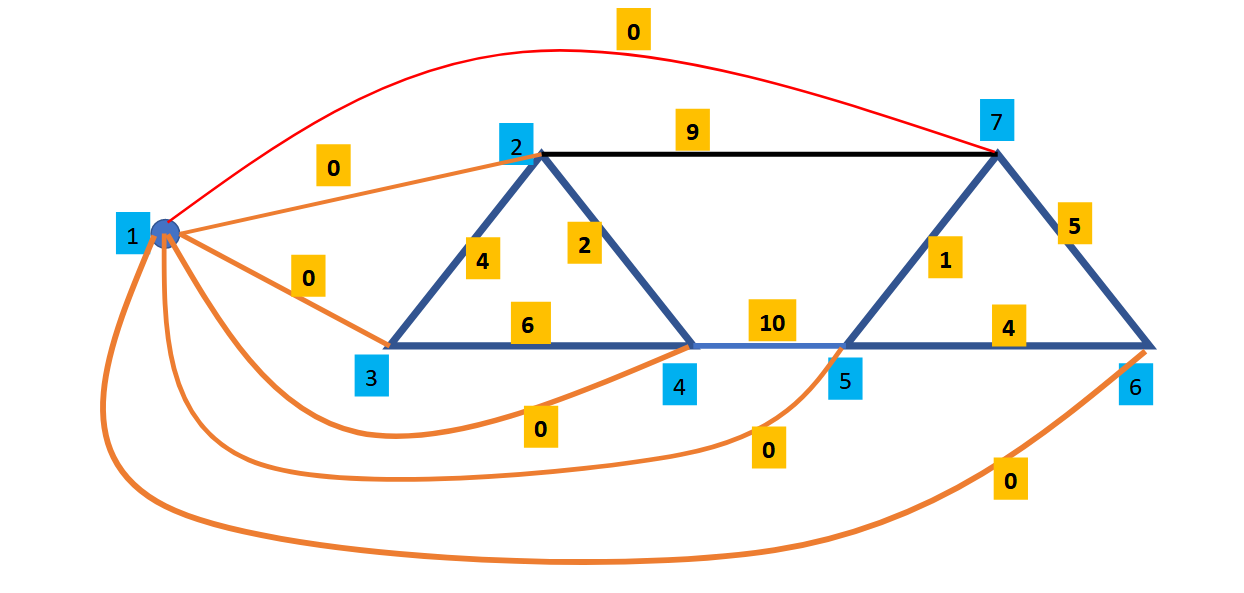

clc
clear all
close all
A =[0 1 1 1 1 1 1;
    1 0 1 1 0 0 1;
    1 1 0 1 0 0 0;
    1 1 1 0 1 0 0;
    1 0 0 1 0 1 1;
    1 0 0 0 1 0 1;
    1 1 0 0 1 1 0];


C = [   0 0 0 0 0 0 0        
    0 0,4,2,0,0,9;
    0 4,0,6,0,0,0 ;
    0 2,6,0,10,0,0;
    0 0,0,10,0,4,1;
    0 0,0,0,4,0,5;
    0 9,0,0,2,5,0;]

C =      0     0     0     0     0     0     0
     0     0     4     2     0     0     9
     0     4     0     6     0     0     0
     0     2     6     0    10     0     0
     0     0     0    10     0     4     1
     0     0     0     0     4     0     5
     0     9     0     0     2     5     0


N = size(A);N=N(1);


tostr = @(i,j) ""+num2str(i)+num2str(j)

tostr = function_handle with value:
    @(i,j)""+num2str(i)+num2str(j)


[i,j] = find(triu(A)==1);
En = length(i);
F = optimvar("F",[ ""+num2str(i) + num2str(j);""+num2str(j) + num2str(i)],"LowerBound",0,"Type","integer","UpperBound",1);
b = optimvar("b",[ ""+num2str(i) + num2str(j);""+num2str(j) + num2str(i)],"LowerBound",0,"Type","integer","UpperBound",N);
C2=[];
C3=[];
C7=[];
O=  sum( C(sub2ind(size(C), i, j)) .* (F(tostr(i,j)) + F(tostr(j,i)))) ;              
C1 = F(tostr(i,j)) + F(tostr(j,i))<=1;
%Run over Nodes
for k=1:(N)
    j_ = find(A(k,:)==1);
    C2 = [ C2 sum(F( "" + tostr(j_',k) ))==1];
    C3 = [ C3 sum(F( "" + tostr(k,j_') ))==1];
    if k>=2
        C7 = [C7 sum(b(tostr(j_',k))) - sum(b(tostr(k,j_'))) == 1];  
    end   
end
j_ = 2:N;
Np = N-1;
C4 = b(tostr(1,j_')) == (Np)*F(tostr(1,j_'));
C5 = b(tostr(i,j)) <= Np*F(tostr(i,j));
C6 = b(tostr(j,i)) <= Np*F(tostr(j,i));


tstour = optimproblem('ObjectiveSense','minimize');
tstour.Objective = O;
tstour.Constraints.C1 = C1;
tstour.Constraints.C2 = C2;
tstour.Constraints.C3 = C3;
tstour.Constraints.C4 = C4;
tstour.Constraints.C5 = C5;
tstour.Constraints.C6 = C6;
tstour.Constraints.C7 = C7;


sol = solve(tstour)

Solving problem using intlinprog.
Set parameter Username
Set parameter TimeLimit to value 7200
Set parameter MIPGapAbs to value 0
Academic license - for non-commercial use only - expires 2023-04-03
Gurobi Optimizer version 9.5.1 build v9.5.1rc2 (win64)
Thread count: 4 physical cores, 8 logical processors, using up to 8 threads
Optimize a model with 68 rows, 56 columns and 196 nonzeros
Model fingerprint: 0xfd8548c8
Variable types: 0 continuous, 56 integer (0 binary)
Coefficient statistics:
  Matrix range     [1e+00, 6e+00]
  Objective range  [1e+00, 1e+01]
  Bounds range     [1e+00, 7e+00]
  RHS range        [1e+00, 1e+00]
Presolve removed 16 rows and 10 columns
Presolve time: 0.00s
Presolved: 52 rows, 46 columns, 172 nonzeros
Variable types: 0 continuous, 46 integer (24 binary)
Found heuristic solution: objective 22.0000000

Root relaxation: objective 1.650000e+01, 26 iterations, 0.00 seconds (0.00 work units)

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 E

sol = struct with fields:
    F: [28×1 double]
    b: [28×1 double]



F.IndexNames{1}{logical(sol.F)}

ans = '13'

ans = '24'

ans = '45'

ans = '57'

ans = '32'

ans = '61'

ans = '76'

route: 1-3-2-4-5-7-6-1

cost: 0 + 4 + 2 + 10 + 1 + 5 = 22;